# View Network Behavior Using tsne - modificado para el dataset BUSI

Adaptacion del tutorial de MATLAB "View Network Behavior Using tsne" para clasificar imagenes del dataset BUSI (Breast Ultrasound Images) en tres categorias: benign, malignant y normal. Se utiliza GoogLeNet preentrenada con transfer learning, siguiendo el mismo flujo que el tutorial original.

## Descargar el dataset BUSI

Descargamos el dataset BUSI desde los servidores de MathWorks y lo descomprimimos.

zipFile = matlab.internal.examples.downloadSupportFile("image", "data/Dataset_BUSI.zip");
filepath = fileparts(zipFile);
unzip(zipFile, filepath);
dataDirBUSI = fullfile(filepath, "Dataset_BUSI_with_GT");

## Cargar y preparar los datos

Creamos el imageDatastore con las imagenes del dataset. Filtramos las mascaras, dividimos en train/validacion y aplicamos data augmentation.

imds = imageDatastore(dataDirBUSI, ...
    IncludeSubfolders=true, LabelSource="foldernames");

%% Eliminamos las imagenes de mascara

imds = subset(imds, find(~contains(imds.Files, "mask")));

% Augmentacion de datos
aug = imageDataAugmenter(RandXReflection=true, ...
    RandYReflection=true, ...
    RandXScale=[0.8 1.2], ...
    RandYScale=[0.8 1.2]);

% Split 65% train / 35% validacion
[trainImds, valImds] = splitEachLabel(imds, 0.65);

% GoogLeNet espera imagenes RGB de 224x224
% Las imagenes BUSI son en escala de grises, convertimos con gray2rgb
augImdsTrain = augmentedImageDatastore([224 224], trainImds, ...
    DataAugmentation=aug, ColorPreprocessing="gray2rgb");
augImdsVal = augmentedImageDatastore([224 224], valImds, ...
    ColorPreprocessing="gray2rgb");

classNames = categories(trainImds.Labels);
numClasses = numel(classNames); % 3 clases: benign, malignant, normal

## Cargar red preentrenada y entrenar

Cargamos GoogLeNet preentrenada y la adaptamos para las 3 clases del dataset BUSI mediante transfer learning.

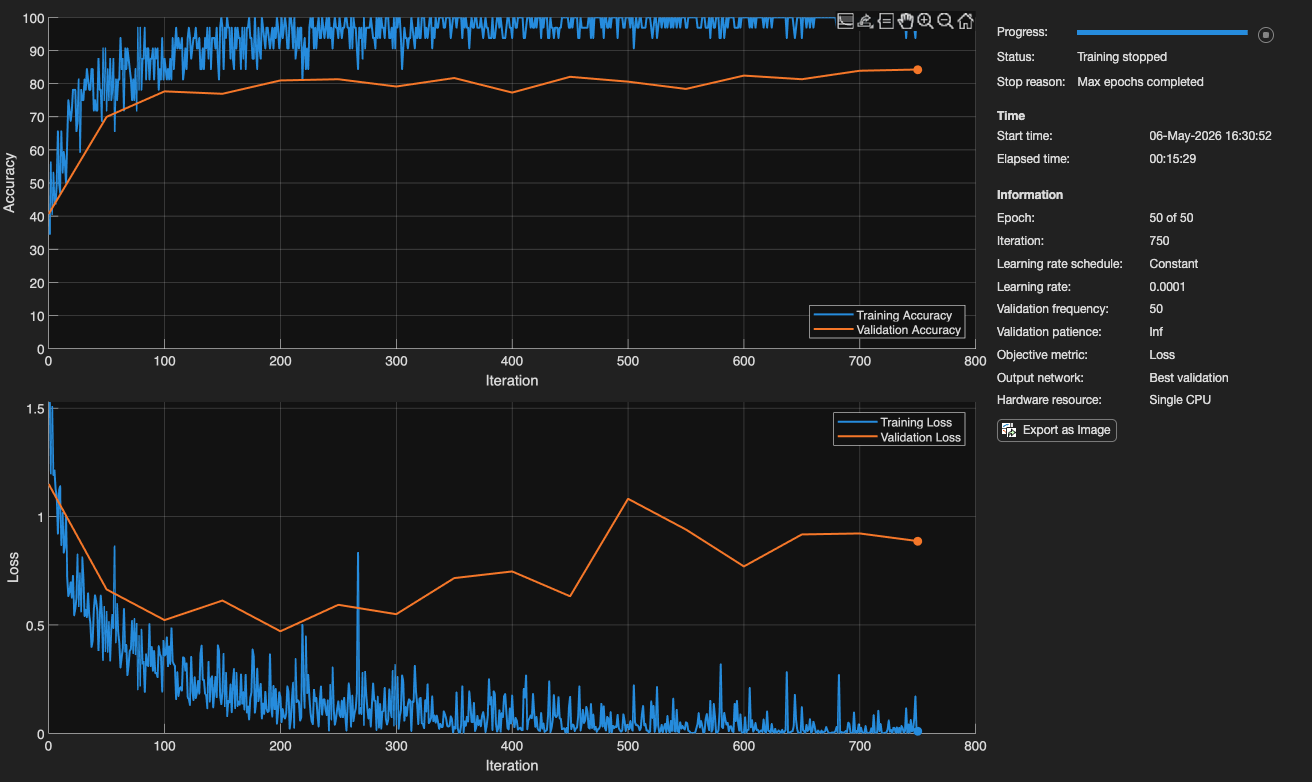

net = imagePretrainedNetwork("googlenet", NumClasses=numClasses);

opts = trainingOptions("adam", ...
    InitialLearnRate=1e-4, ...
    MaxEpochs=50, ...
    ValidationData=augImdsVal, ...
    Verbose=false, ...
    Plots="training-progress", ...
    MiniBatchSize=32, ...
    Metrics="accuracy");

rng default
net = trainnet(augImdsTrain, net, "crossentropy", opts);

## Clasificar y obtener la matriz de confusion

Clasificamos las imagenes de validacion y generamos la matriz de confusion.

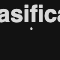

scores = minibatchpredict(net, augImdsVal);
YPred = scores2label(scores, classNames);

figure();
confusionchart(valImds.Labels, YPred, ColumnSummary="column-normalized");
title("Matriz de confusion - Clasificacion BUSI (GoogLeNet)");

## Estrategias de referencia

Comparamos el resultado de la red con dos clasificadores triviales: uno que elige clase aleatoriamente y otro que siempre predice la misma clase.

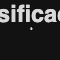

numVal = numel(valImds.Labels);

% Baseline 1: clasificacion aleatoria
rng default
randomIdx = randi(numClasses, numVal, 1);
YRandom = categorical(classNames(randomIdx)', classNames);

figure();
confusionchart(valImds.Labels, YRandom, ColumnSummary="column-normalized");
title("Baseline: clasificacion aleatoria");

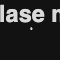


% Baseline 2: siempre la clase mas frecuente
[~, mostFreqIdx] = max(countcats(trainImds.Labels));
YAlways = categorical(repmat(classNames(mostFreqIdx), numVal, 1), classNames);

figure();
confusionchart(valImds.Labels, YAlways, ColumnSummary="column-normalized");
title("Baseline: siempre la clase mas frecuente (" + classNames(mostFreqIdx) + ")");